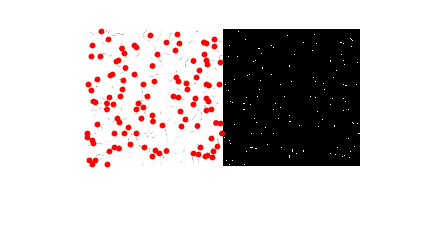

I = imread('C:\Users\victo\Google Drive\DATA\HT1080\Orient\01082018_Orient_s311.tif',59);

fun = @(B) ...
    sqrt((sum(sum(cos(2*B.data)))/(size(B.data,1)*size(B.data,2)))^2 ...
    +(sum(sum(sin(2*B.data)))/(size(B.data,1)*size(B.data,2)))^2);

I2 = blockproc(I,[5 5],fun,'PadMethod','replicate','UseParallel',true);

im2 = I2 < .6;%.2; % make binary image to use regionprops

s = regionprops('table', im2,'centroid');
r_Circ = 10;
s_x = s.Centroid(:,1);
s_y = s.Centroid(:,2);
imshowpair(I2,im2,'montage');hold on
scatter(s_x,s_y,20,'red','filled');hold off

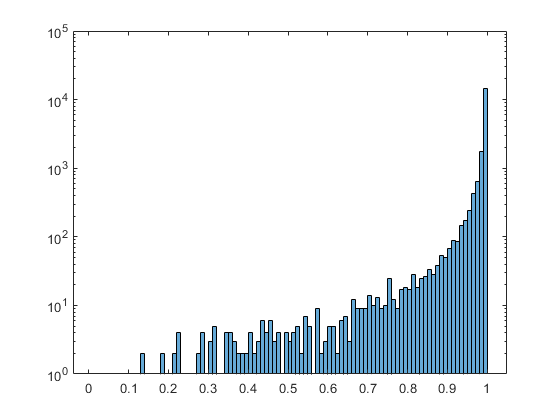

figure; histogram(I2);set(gca,'YScale','log')

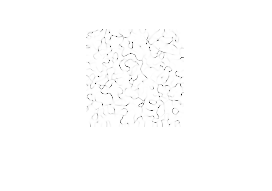

I2 = fast_order_parameter(I,5,5);
figure;
imshow(I2);

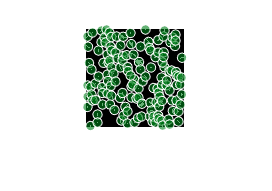


Q=ordermatrixglissant_overlap(I,15,2);
% imshow(Q);

[l,w] = size(I2);
[L,W] = size(Q);
[xx,yy] = meshgrid(1:w,1:l);
[XX,YY] = meshgrid(1:W,1:L);
scaling = L/l;
I2_L = interp2(xx,yy,I2,XX,YY,'spline',0); %Xorig,Yorig,uu,Xu,Yu,'cubic',0

im2 = I2 < min(I2(:))+0.8;
se = strel('disk',2);
im2 = imdilate(im2,se);
im2 = imerode(im2,se);


imshow(im2);hold on
s = regionprops('table', im2,'centroid');
s_x = s.Centroid(:,1);
s_y = s.Centroid(:,2);
scatter(s_x,s_y,...
    50,'filled','MarkerFaceColor', [0 .5 .1],...
    'MarkerFaceAlpha',.6,...
    'MarkerEdgeColor',[1 1 1]);



figure;
imshow(Q); hold on

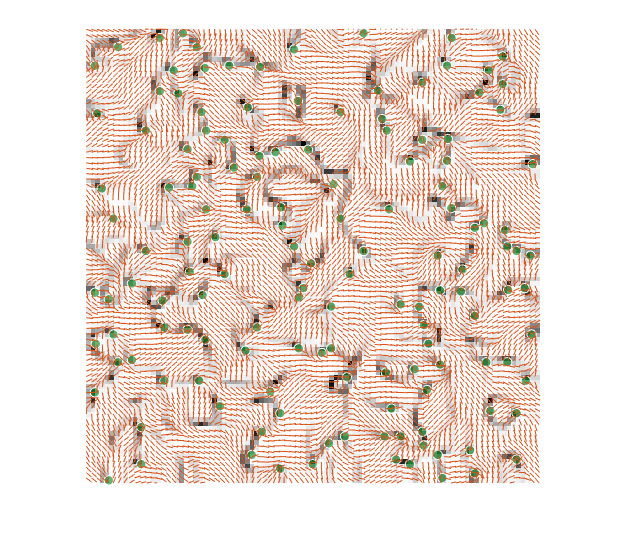

scatter(scaling*s_x,scaling*s_y,...
    50,'filled','MarkerFaceColor', [0 .5 .1],...
    'MarkerFaceAlpha',.6,...
    'MarkerEdgeColor',[1 1 1]);

[LI,WI] = size(I);
[XXI,YYI] = meshgrid(1:WI,1:LI);
step = 8;
q1 = quiver(XXI(1:step:end,1:step:end),YYI(1:step:end,1:step:end),...
    cos(I(1:step:end,1:step:end)),sin(I(1:step:end,1:step:end)));
q1.ShowArrowHead = 'off';
hold off

function Q = ordermatrixglissant_overlap(A,a,d)

%A=imread(d);
Q=[];

ii=1;
for i=1:floor(a/d):size(A,1)-a+1
    jj=1;
    for j=1:floor(a/d):size(A,2)-a+1
        
        B=A(i:i+a-1,j:j+a-1);
        
        
        q=sqrt((sum(sum(cos(2*B)))/(size(B,1)*size(B,2)))^2+(sum(sum(sin(2*B)))/(size(B,1)*size(B,2)))^2);
        %q=(sum(sum(cos(2*B)))/(size(B,1)*size(B,2)));
        
        
        % q=(sum(sum(cos(B)))/(size(B,1)*size(B,2)));
        
        %         Q(i:i+a-1,j:j+a-1)=q;
        
        Q(i:i+a-1,j:j+a-1)=q;
        jj=jj+1;
    end
    ii=ii+1;
end
end